# A Little Statistics

## 1.A) 

A normal distribution, also called a bell curve or a Gaussian distribution, $P\left(x\right)=\frac{1}{\sigma \sqrt{2\pi }}e^{\frac{{-\left(x-\mu \right)}^2 }{2\sigma^2 }}$ is a very common probability distribution that can be used to represent the probability of things like the height of people, or the scores on a test. The integral of the standard normal distribution is known as the error function. $X\sigma$ or the z-score is how far a measurement is from the mean, or also a measure of how liekly that measurement would occur by random chance if the random chance follows a normal distribution.

d = random('Normal', 0., 1, [1,100000]);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on
xlim([-6,6])
x = linspace(-5,5,10000);
pd = makedist("Normal","mu",0.,"sigma",1);
plot(x,pdf(pd,x),"LineWidth",2);
set(gca,'YScale','log')
title('Standard Normal Distribution Probability Distribution Function')
xlabel('Z score')
ylabel('Probability')
hold off

## B) 

Plotting the error function or integral of the normal distribution:

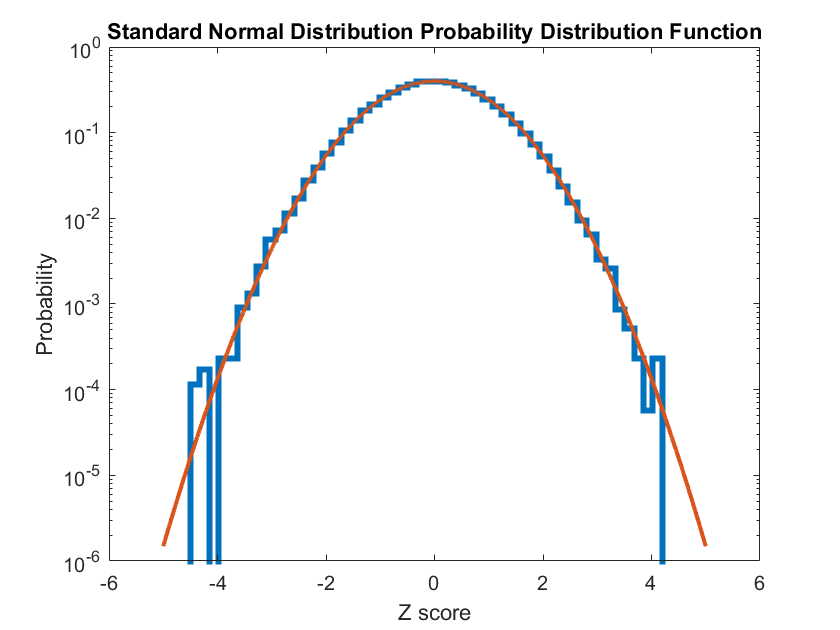

hold off

plot(x,normcdf(x),'LineWidth',3)
%set(gca,'YScale','log')
xlim([-6,6])
title('Standard Normal Distribution Cumulative Distribution Function')
xlabel('Z score')
ylabel('Probability')

The following are the values of the error function for 5 different values of sigma or 5 different z-scores:

ERF = zeros(5,1);
randNums = zeros(5,1);
for i = 1:5
    randNums(i) = 3*rand;
    ERF(i) = normcdf(randNums(i));
end

ZScoreVsProbability = zeros(5,2);
ZScoreVsProbability(:,1) = randNums;
ZScoreVsProbability(:,2) = ERF;
ZScoreVsProbability

ZScoreVsProbability =     1.1058    0.8656
    2.7101    0.9966
    2.7828    0.9973
    2.5231    0.9942
    1.9830    0.9763


## C) 

Calculating the sigma number for some common probabilities (1,2,3, and 7 sigmas):

probabilities = [0.5, 0.5, 0.5, 0.5] + ([ 0.68, 0.95, 0.997, 0.999999999997440]/2);
sigmas = norminv(probabilities)

sigmas =     0.9945    1.9600    2.9677    7.0000


## D)

 I had no negatives in the values that I chose, but if you had a probability of less than 50%, this would fall to the left of the mean on a normal distribution, and would thus have a negative z-score since this would be to the left of 0 on a standard normal distribution. This is different from sigma values which are always reported as positive regardless of which side of the curve it comes from, i.e. a measurement that has 7 sigma could come from the left or right tail of a distribution, while the z-score has a sign accordion to which side of the mean it is from. See the example below for 30% probability:

negativeZScore = norminv(0.3)

negativeZScore = -0.5244

## 2.A) 

I am choosing a Rayleigh distribution, which is a distribution of positive random variables. It can be though of as a chi-squared distribution when dealing with two dimensions or degrees of freedom instead of one, such as random velocities on a 2-d surface. It can also represent the magnitude of a normal distribution of complex numbers, thus the Rayleigh distribution arises often in physics when dealing with equation that have complex numbers or when there are 2 degrees of freedom for some measurement.

## B)

Here is a plot of 100k samples of a rayleigh distribution with the sigma parameter set to 1:

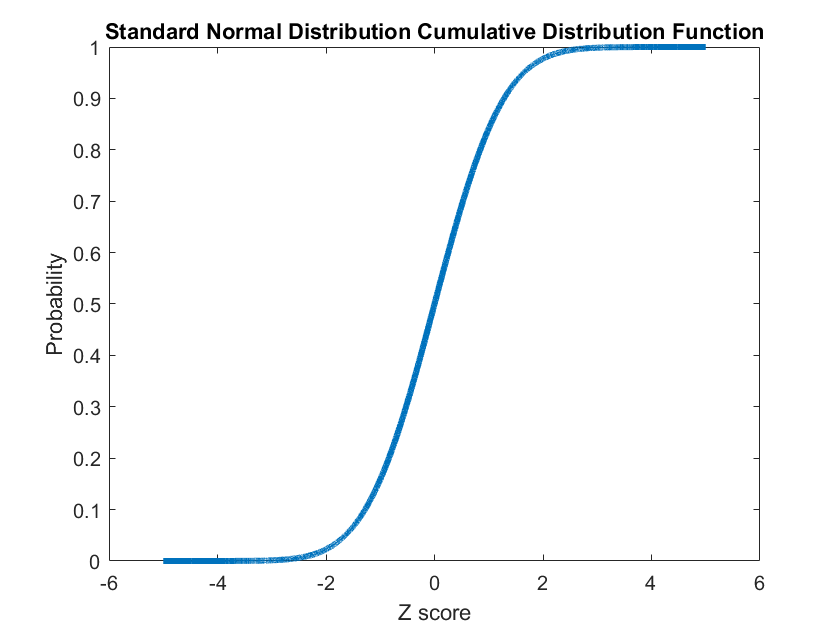

%generate 100k random points in a rayleigh distribution
hold off

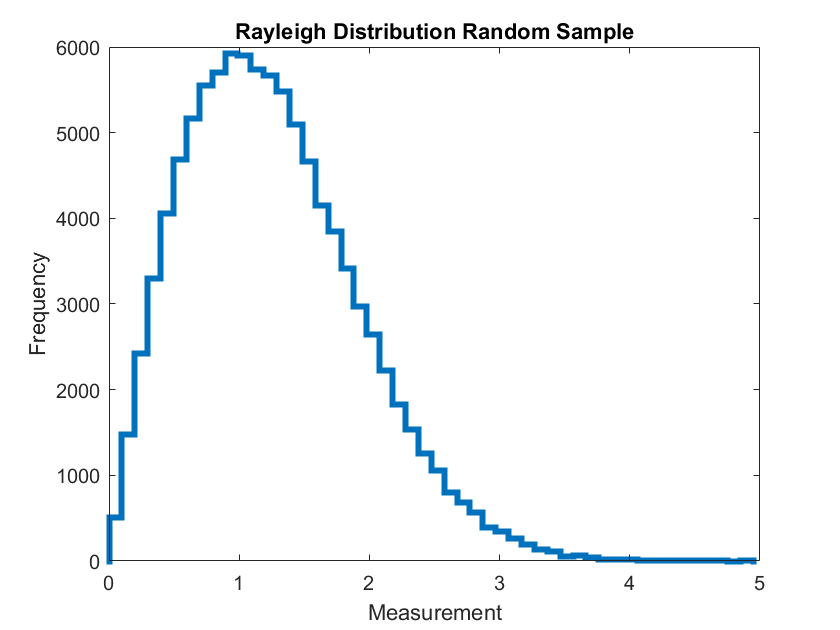

d = raylrnd(1, 1, 100000);  
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3)
xlim([0,5])
title('Rayleigh Distribution Random Sample')
xlabel('Measurement')
ylabel('Frequency')

The probability density function for the Rayleigh distribution is as follows: $P\left(x,\sigma \right)=\frac{x}{\sigma^2 }e^{\frac{-x^2 }{2\sigma^2 }}$. And here is the previous data normalized and with an overlayed curve on a semilog plot:

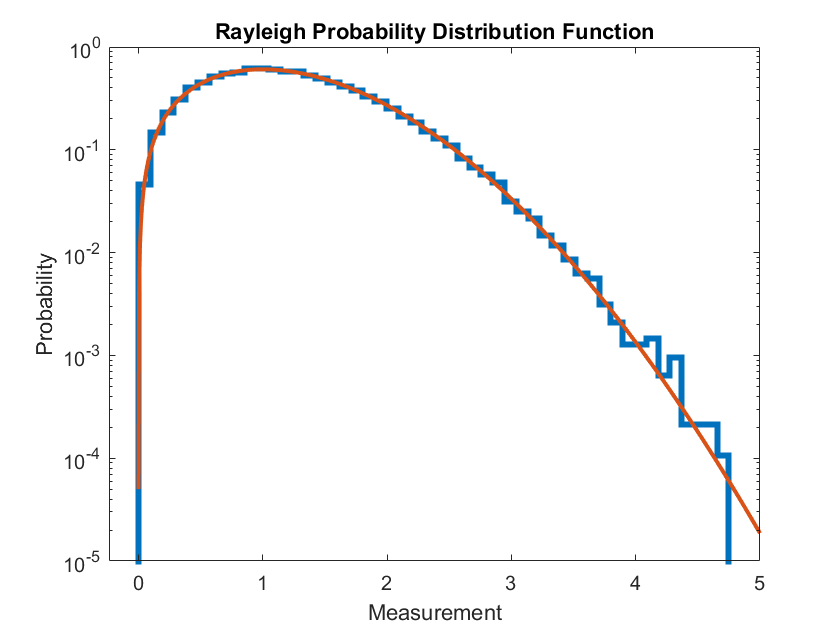

d = raylrnd(1, 1, 100000);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on
x = linspace(0,5,100000);
pd = raylpdf(x, 1);
plot(x,pd,"LineWidth",2);
set(gca,'YScale','log')
title('Rayleigh Probability Distribution Function')
xlabel('Measurement')
ylabel('Probability')
hold off

It is apparent on the semilog plot that begining at about 4 on the x-axis, the noise becomes increasingly noticeable, and values much larger than this are extreemely unlikely due to a random sampling of the distribution.

## 3. A) 

I will choose a signal candidate measurement of 7 units

## B) 

I want to ask how likely is it that this signal measurement can be explained by random noise represented by the rayleigh distribution above.

## C) 

the probability of a measurment 7 or more extreme is equal to the following integral where I have chosen sigma as 1:


$$\int_9^{\infty } \frac{x}{\sigma^2 }e^{\frac{-x^2 }{2\sigma^2 }} \textrm{dx}=\int_9^{\infty } x*e^{\frac{-x^2 }{2}} \textrm{dx}=1-\int_{\infty }^9 x*e^{\frac{-x^2 }{2}} \;\textrm{dx}\;\;$$


## D)

This integral can be easily calculated using the cdf function on matlab:

signalProbability = 1 - raylcdf(7,1)

signalProbability = 2.2897e-11

## E)

To find the sigma value of this probability, I will simply do the following:

sigmaValue = abs(norminv(signalProbability))

sigmaValue = 6.5840

This leaves us with a probability of about 6.58 sigma.

## 4.

Initially I tried using a signal of 9 units, but the probability was so small, that matlab rounded it to 0. 

signal9 = 1 - raylcdf(9,1)

signal9 = 0

This shows that the rayliegh distribution very quickly approaches 0 for values that are even a little bit ouside the main range of about 0-5 for the parameters that I chose here.

A signal of value 5, which is seeminlgy not impossible has the following probability and sigma value:

signal5probability = 1 - raylcdf(5,1)

signal5probability = 3.7267e-06

sigma5 = abs(norminv(signal5probability))

sigma5 = 4.4803

A probability of 4.48 sigma is large, but there is still some doubt of if this may have been caused by random noise, whereas a signal of 7 or 9 is almost certainly not caused by random noise.

# Non-continuous Distributions

## 1.A)

I am looking at the Poisson Distribution, which is a limiting case of the binomial distribution where the probability of the observed event is very small at any one time, and the number of trials is infinite, which occurs when looking at the probability of a discrete event in some time period which has a seeminly infinite number of moments of time. For example, the number of atoms that decay in a minute can be modeled by a poisson distribution since there is a very small chance of any one atom decaying at any given moment, but for a large enough sample given enough time, there is still some expected total number of decays that will occur. The equation for the possion distribution is $P\left(x=k\right)=\frac{\lambda^k *e^{-\lambda } }{k!}$where x is a discrete random variable, k is the number of occurences, and $\lambda$ is both the expected value and variance.

## B)

Probability distribution function for the Poisson distribution with a $\lambda$ of 2:

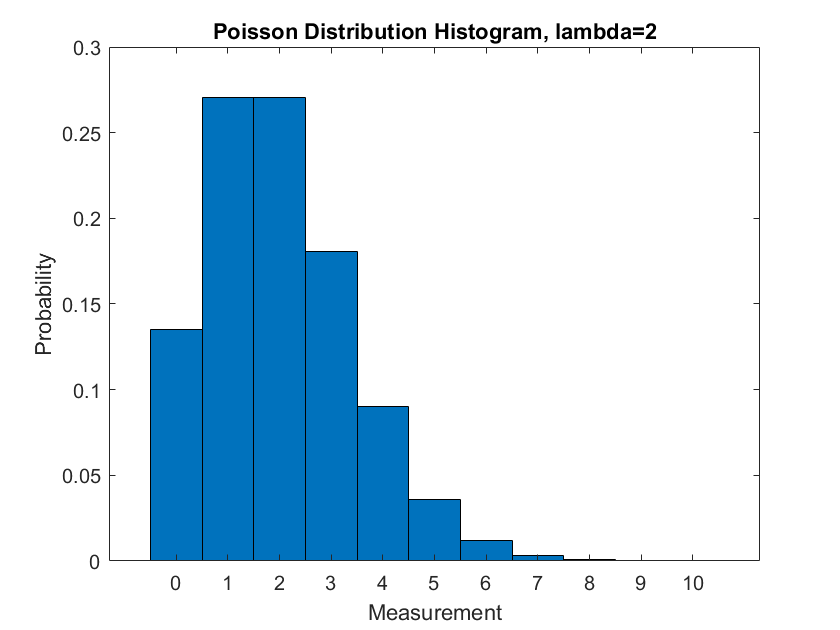

x = 0:10;
y = poisspdf(x,2);
figure
bar(x,y,1)
title('Poisson Distribution Histogram, lambda=2')
xlabel('Measurement')
ylabel('Probability')

With a small lambda such as above, the distribution has a large bar at 0, and a small tail to the left. At large lambda values, such as 50 shown below, the poisson distribution begins to look like a normal distribution.

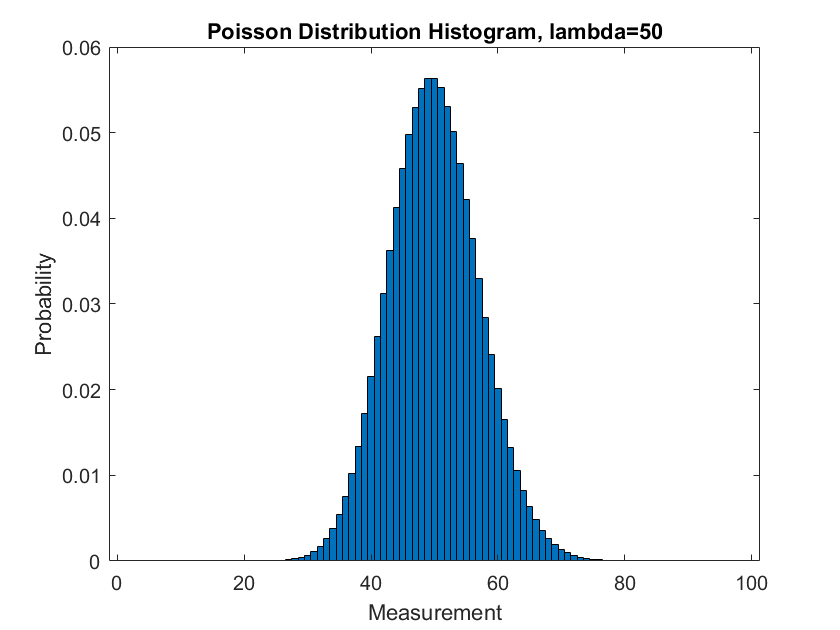

x = 0:100;
y = poisspdf(x,50);
figure
bar(x,y,1)
title('Poisson Distribution Histogram, lambda=50')
xlabel('Measurement')
ylabel('Probability')

Below are the cumulative distribution functions for lambdas of 2 and 50, again notice how for large lambda the distribution looks nearly identical to a normal distribution centered at lambda.

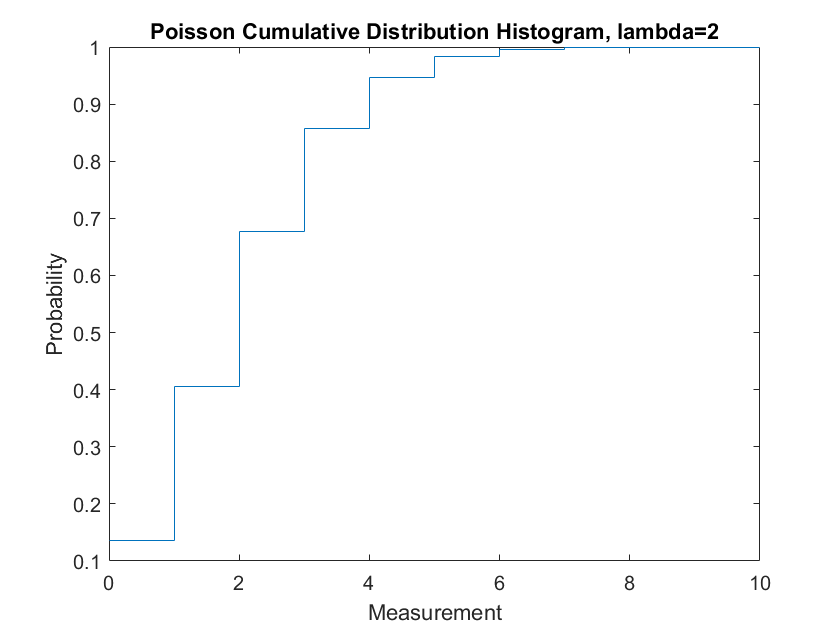

x = 0:10;
y = poisscdf(x,2);
figure
stairs(x,y)
title('Poisson Cumulative Distribution Histogram, lambda=2')
xlabel('Measurement')
ylabel('Probability')

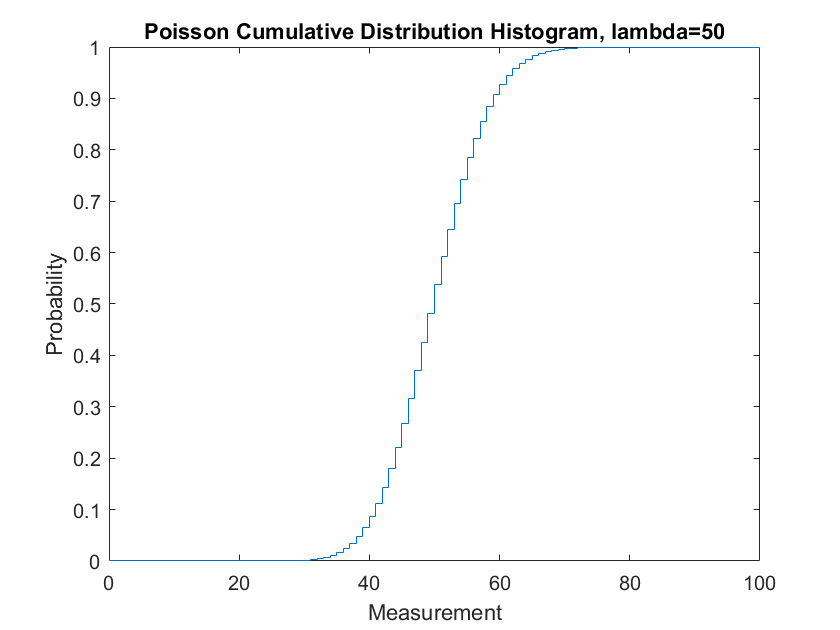

x = 0:100;
y = poisscdf(x,50);
figure
stairs(x,y)
title('Poisson Cumulative Distribution Histogram, lambda=50')
xlabel('Measurement')
ylabel('Probability')

## C)

I will look at what the probability of a measurement of 15 units is due to a random sampling of a poisson distribution with a lambda of 2. This is equivalent to the following sum: $\sum_{k=15}^{\infty } \frac{\lambda^k *e^{-\lambda } }{k!}$. Here is the calculation of this probability and the corresponding sigma value

poissProb = 1 - poisscdf(15, 2)

poissProb = 4.7997e-10

poissSigmaValue = abs(norminv(poissProb))

poissSigmaValue = 6.1159

## D)

Since the observed quantity is discrete, so must the probabilities and corresponding sigma values. This is liekly not a big deal for experiments because the values can more or less be treated the same as for continuous distributions as far as analysis goes.

## E)

It makes sense to have continuous parameters for a discrete distribution since it makes perfect sense for lambda to be any number. The expected mean is simply the value expected to be measured if an infinite number of trials were conducted, and gthe same for sigma and lambda and the other continuous parameters. The discrete observed quantities and probabilities must be discrete because they are associated with a sigle measurement.